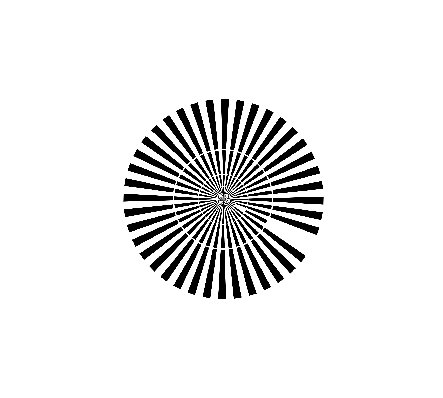

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

M = 10;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
seleccionador = 1; 

if seleccionador == 1
    dx = 200*nm;
elseif seleccionador == 2
    dx = 60*nm;
end

% d = 100*nm;
d = 60*nm;

dy = dx;

% Longitud de Onda de emisión

lambda = 700*nm;


% Apertura númerica
AN = 0.3;

estrella = imread('SiemensStar_2048_AD.png');
estrella2 = imresize(estrella,4096/2048);
%estrella = imresize(estrella,Nx/780);
estrella = rgb2gray(estrella);
imshow(estrella)
colormap("gray")


%La imagen pasará por un primer lente, el cual es un 
% objetivo 10x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f2 = 200*mm;

dd = lambda/(2*AN)

dd = 1.1667e-06


%Microscopio de un foton 

[salidaPura, observacion, pupila, spot] = microscopio(estrella,d,M,f2,AN, Nx, Ny, dx, dy, lambda);

rpupila = 175.5429

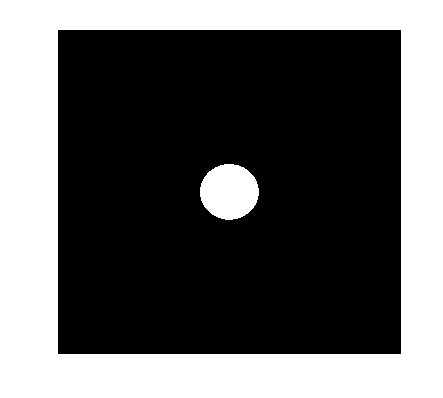

observacion = imrotate(observacion,180);
imagesc(pupila)
colormap("gray")
axis("off")

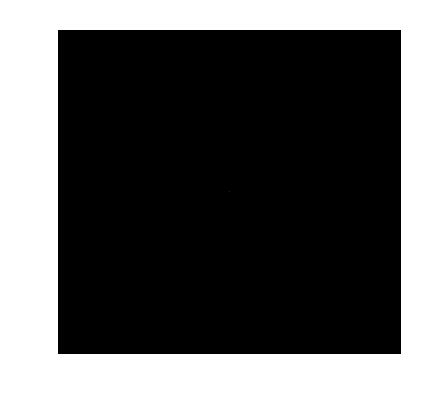

imagesc(spot)
colormap("gray")
axis("off")

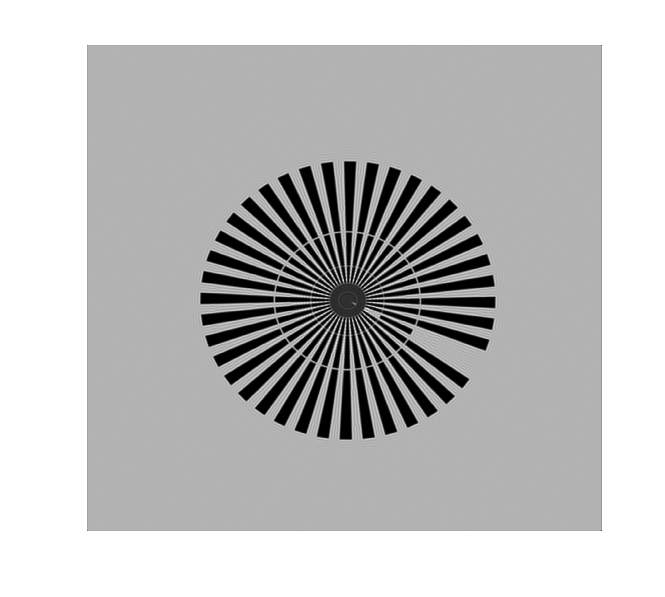

imagesc(observacion)
colormap("gray")
axis("off")